# Taller 7

### 26/09/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 5 y 6*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

- **Otros recursos sobre manejo de MATLAB practicas básicas: ***https://matlabacademy.mathworks.com/es/*

*Recordar documentarse en cada una de las rutinas disponibles del curso y de MATLAB para afrontar distintas situaciones, MATLAB es su aliado.*

#### *        Métodos de interpolación polinomial*

`    [C, D] = newpoly (X, Y), `Polinomio de Newton

            - X es un vector que contiene la lista de abscisas

            - Y es un vector que contiene la lista de ordenadas

            - C es un vector que contiene los coeficientes del

                polinomio interpolante de Newton

            - D es la tabla de diferencias divididas

`    [C, L] = lagran (X, Y), `Polinomio de Lagrange

            - X es un vector que contiene una lista de las abscisas

            - Y es un vector que contiene una lista de las ordenadas

            - C es una matriz que contiene los coeficientes del

                polinomio interpolante de Lagrange

            - L es una matriz que contiene los coeficientes de los

                polinomios de Lagrange

`    [C, X, Y] = cheby (fun, n, a, b), `Nodos & Generador de Chebyshev

            - fun es la funcion introducida con @

            - N es el grado del polinomial interpolante de Chebyshev

            - a es el extremo izquierdo

            - b es el extremo derecho

            - C es la lista de coeficientes para el polinomio

            - X contiene las abscisas

            - Y contiene las ordenadas

`    [X, Y] = nodoschebyshev (fun, n, a, b), `Nodos de Chebyshev

            - fun es la funcion introducida con @

            - N es el grado del polinomial interpolante de Chebyshev

            - a es el extremo izquierdo

            - b es el extremo derecho

            - X contiene las abscisas

            - Y contiene las ordenadas

#### *        Métodos de interpolación por minimos cuadrados*

`    C = lspoly (X, Y, M), `Polinomio de minimos cuadrados

             - X es el vector de abscisas   1 x n

            - Y es el vector de ordenadas  1 x n

            - M es el grado del polinomio por minimos cuadrados

            - C es la lista de coeficientes para el polinomio

`    [A, B] = lsline (X, Y), `Linea de minimos cuadrados

            - X es el vector de abscisas   1 x n

            - Y es el vector de ordenadas  1 x n

            - A es el coeficiente de  x  en  Ax + B

            - B es el coeficiente constante en  Ax + B

#### *        Errores asociados*

        `Errores asociados a la aproximación de polinomios de Newton y Lagrange`

 
$$|E\left(x\right)|\le \;\frac{f^{\left(n+1\right)} \left(x^* \right)}{\left(n+1\right)!}\;\prod_{i=0}^n \left(x-x_i \right)$$


        `Errores asociados a la aproximación de polinomios con nodos de Cheby dentro del intervalo estandar `$I=\;\left\lbrack -1,1\right\rbrack$


$$|E\left(x\right)|\le \frac{1}{2^n \;\left(n+1\right)!}\;\max \left\lbrace f^{\left(n+1\right)} \left(\xi \left(x\right)\right)\right\rbrace$$


        `Errores asociados a la aproximación de polinomios con nodos de Cheby dentro del intervalo estandar `$I=\;\left\lbrack a,b\right\rbrack$


$$|E\left(x\right)|\le \frac{2\;{\left(b-a\right)}^{n+1} }{4^{n+1} \;\left(n+1\right)!}\;\max \left\lbrace f^{\left(n+1\right)} \left(\xi \left(x\right)\right)\right\rbrace$$


        `Errores asociados a la aproximación de funciones usando el métodos de minimos cuadrados`


$$|E\left(x\right)|=\sum_{i=0}^n |\;p\left(x_i \right)\;\;-\;f\left(x_i \right)|^2$$


***Nota:**** este método es equivalente al métodod de *`lsline0`

Recordar documentarse en cada una de las rutinas disponibles del curso y de MATLAB para afrontar distintas situaciones, MATLAB es su aliado.

`Tabla de cambios de variable, para modelos`

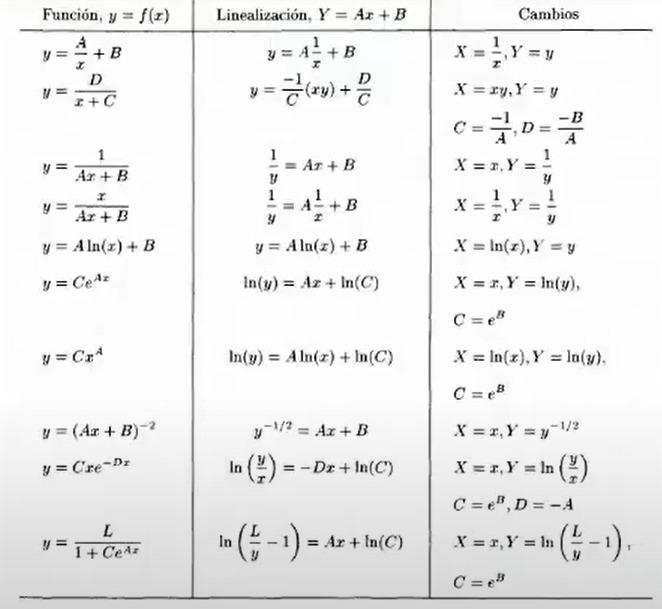

### Interpolación y Aproximación

*Desarrollaremos el sexto taller, para esta sección resolveremos *$9,10\;\&\;11$.

**9. **La ley de Hooke establece $F=k\;x$, donde F es la fuerza *(dinas)* que es necesario ejercer para

conseguir que un resorte o un muelle se estire una longitud $x$ *(cm)* desde su posición de equilibrio.

*Aproxime la constante k con base en los datos de la siguiente tabla obtenidos por medio de un*

*experimento:*


$$x_i$$
      
$$0\ldotp 2$$
      
$$0\ldotp 4$$
      
$$0\ldotp 6$$
      
$$0\ldotp 8$$
      
$$1\ldotp 0$$



$$F_i$$
     
$$5\ldotp 3$$
    
$$10\ldotp 6$$
    
$$15\ldotp 9$$
     
$$21\ldotp 2$$
    
$$26\ldotp 4$$


clear
X = .2:.2:1;
F = [5.3 10.6 15.9 21.2 26.4];

[k, ~] = lsline(X, F)

**10.** Con el objeto de medir la aceleración de la gravedad, se recolectó experimentalmente la siguiente

colección de información relacionada con el tiempo que tarda un objeto en llegar al suelo según la

altura desde la que se deja caer. La relación funcional es $d=1/2\;g\;t^2$. La distancia se mide en metros

*(m)* y el tiempo se mide en segundos *(s).*

`Tiempo (s)         0.2      0.4      0.6      0.8      1.0`

`distancia (m)   0.1960   0.7850   1.7665   3.1405   4.9075`

clear
t = .2:.2:1;
d = [.1960 .7850 1.7665 3.1405 4.9075];

C = lspoly(t, d, 2);

k = 26.4000

g = 2 * C(1)

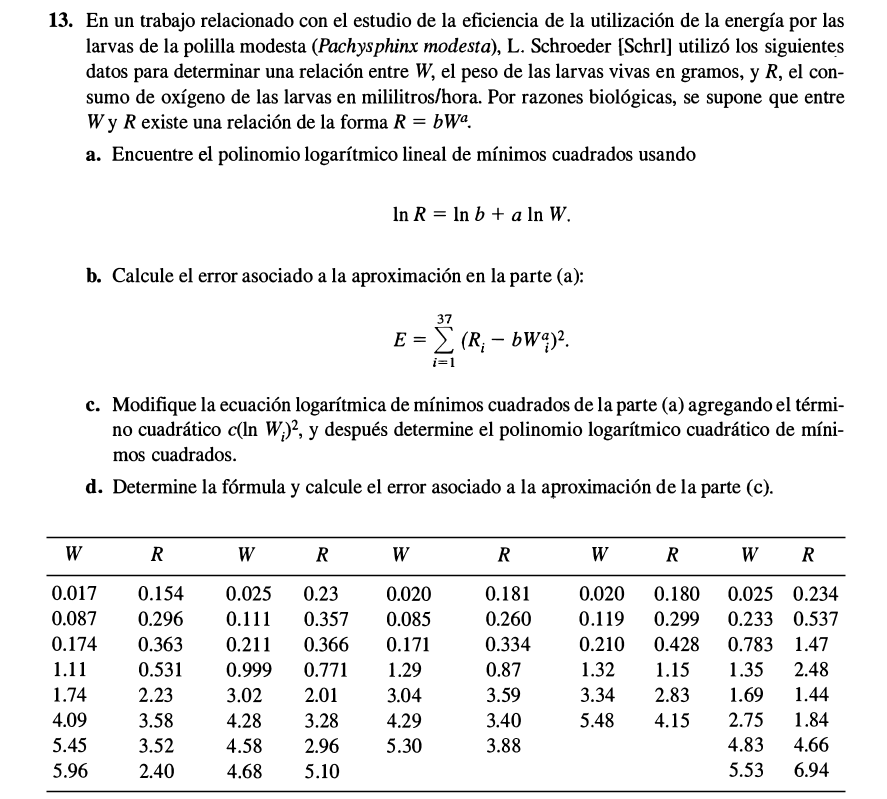

clear
W = [.017 .087 .174 1.11 1.74 4.09 5.45 5.96 .025 .111 .211 .999 3.02 4.28 4.58 4.68 .02 .085 ...
    .171 1.29 3.04 4.29 5.30 .020 .119 .210 1.32 3.34 5.48 .025 .233 .783 1.35 1.69 2.75  4.83 5.53];
R = [.154 .296 .363 .531 2.23 3.58 3.52 2.4 .23 .357 .366 .771 2.01 3.28 2.96 5.10 .181 .260 ...
    .334 .87 3.59 3.40 3.88 .180 .299 .428 1.15 2.83 4.15 .234 .537 1.47 2.48 1.44 1.84 4.66 6.94];


g = 9.8161

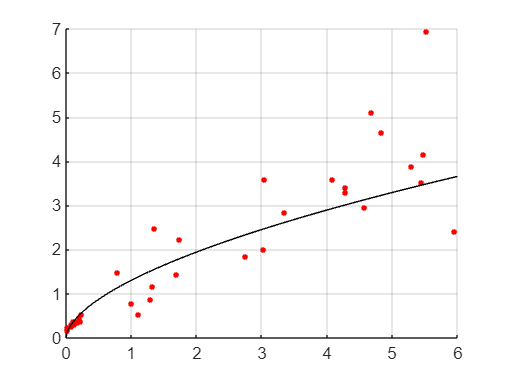

[a, c] = lsline(log(W), log(R));
b = exp(c);
F = @(w) b .* w.^a;

clf('reset')
hold on
plot(W, R, '.r', 'MarkerSize', 10, 'DisplayName', 'Datos')
fplot(F, [0, 6], 'k', 'DisplayName', 'Modelo 1')
grid on
hold off
S = lspoly(log(W), log(R), 10);
G = @(w) exp(polyval(S, log(w)));

clf('reset')
hold on
plot(W, R, '.r', 'MarkerSize', 10, 'DisplayName', 'Datos')
fplot(F, [0, 6], 'k', 'DisplayName', 'Modelo 1')
fplot(G, [0, 6], 'b', 'DisplayName', 'Modelo 2')

legend('Location', 'best')
grid on
hold off
ErrorF = sum( (R - F(W)).^2 )
ErrorG = norm(R - G(W))^2

### Spline Cubico

*Desarrollaremos el septimo taller, para esta sección resolveremos *$2,4,6\;\&\;7$.

**2. **Un spline cúbico natural S definido en $\left\lbrack 1,3\right\rbrack$ se define asi:


$$S\left(x\right)=\left\lbrace \begin{array}{ll}
S_0 \left(x\right)=1+B\left(x-1\right)-{D\left(x-1\right)}^3  & 1\le x<2\\
S_1 \left(x\right)=\;1+b\left(x-2\right)-\frac{3}{4}{\left(x-2\right)}^2 +d\;{\left(x-2\right)}^3  & 2\le x\le 3
\end{array}\right.$$


Si $S$ interpola la tabla

`x   `` 1    2    3`

`y  ``  1    1    0`

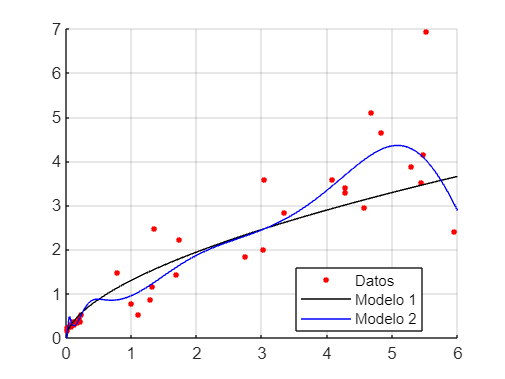

clear
X = 1:3;
Y = [1 1 0];

S = csnatural(X, Y)
GraficaCercha(X, Y, S)

**4. **Indique si la función $S\left(x\right)$ dada por


$$S\left(x\right)$$
    
$$\begin{array}{l}
S_0 \left(x\right)=-x^3 +x+1\\
S_1 \left(x\right)={4\;\left(x-1\right)}^3 -3\;{\left(x-1\right)}^2 -2\;\left(x-1\right)+1\\
S_2 \left(x\right)=-3\;{\left(x-2\right)}^3 +9\;{\left(x-2\right)}^2 +4\;\left(x-2\right)
\end{array}$$
    
$$\begin{array}{l}
0\le \;x <1\\
1\le \;x <2\\
2\le \;x \le 3
\end{array}$$


es o no es el spline cúbico natural para la tabla

`x  ``  0    1    2     3`

`y   `` 1    1    0    10`

clear

ErrorF = 25.3018

syms S(x) [0 2]

ErrorG = 16.3897


X = 0:3;
Y = [1 1 0 10];

S0(x) = - x^3 + x + 1;
S1(x) = 4 *(x - 1)^3 - 3 *(x - 1)^2 - 2 *(x - 1) + 1;
S2(x) = -3 *(x - 2)^3 + 9 *(x - 2)^2 + 4 *(x - 2);

dS0(x) = diff(S0, x);
dS1(x) = diff(S1, x);
dS2(x) = diff(S2, x);

d2S0(x) = diff(dS0, x);
d2S1(x) = diff(dS1, x);

S =    -0.2500         0    0.2500    1.0000
    0.2500   -0.7500   -0.5000    1.0000


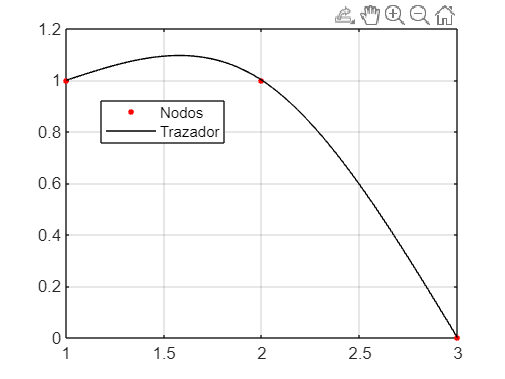

d2S2(x) = diff(dS2, x);


% Continuidad
S0(1) == S1(1), S1(2) == S2(2)
% Diferenciabilidad
dS0(1) == dS1(1), dS1(2) == dS2(2)
% Curvatura
d2S0(1) == d2S1(1), d2S1(2) == d2S2(2)
% Condición de Naturalidad
d2S0(0), d2S2(3)
% Interpolación de la tabla
S0(0), S2(3)
clf('reset')
hold on
plot(X, Y, '.r', 'MarkerSize', 10)
fplot(S0, [0, 1], 'k')
fplot(S1, [1, 2], 'k')
fplot(S2, [2, 3], 'k')
legend('Datos', 'Trazador', 'Location', 'best')
grid on
hold off

**6. **Determine si existen coeficientes $a,b,c\;y\;\;d$ de tal forma que la función


$$S\left(x\right)$$
    
$$\begin{array}{l}
S_0 \left(x\right)=\frac{5}{7}{\;\left(x+2\right)}^3 -\frac{47}{7}\;\left(x+2\right)+8\\
S_1 \left(x\right)=a\;{\left(x+1\right)}^3 +b\;{\left(x+1\right)}^2 +c\;\left(x+1\right)+d\\
S_2 \left(x\right)=\frac{1}{21}\;{\left(x-1\right)}^3 -\frac{3}{7}\;{\left(x-1\right)}^2 -\frac{8}{7}\;\left(x-1\right)-2
\end{array}$$
    
$$\begin{array}{l}
-2\le \;x <-1\\
-1\le \;x \le 1\\
\;\;\;1<\;x \le 4
\end{array}$$


sea un spline cúbico en el intervalo $\left\lbrack -2,4\right\rbrack$. *¿Es un spline cúbico natural? *

clear
syms S(x) [0 2]
syms a b c d real

S0(x) = 5/7 *(x + 2)^3 - 47/7 * (x + 2) + 8;
S1(x) = a *(x + 1)^3 + b *(x + 1)^2 + c *(x + 1) + d;

$$ans = 1=1$$

$$ans = 0=0$$

S2(x) = 1/21 *(x - 1)^3 - 3/7 *(x - 1)^2 - 8/7 *(x - 1) - 2;


$$ans = -2=-2$$

$$ans = 4=4$$

dS0(x) = diff(S0, x);
dS1(x) = diff(S1, x);

$$ans = -6=-6$$

$$ans = 18=18$$

dS2(x) = diff(S2, x);


$$ans = 0$$

$$ans = 0$$

d2S0(x) = diff(dS0, x);
d2S1(x) = diff(dS1, x);

$$ans = 1$$

$$ans = 10$$

d2S2(x) = diff(dS2, x);

% Continuidad
Eq1 = S0(-1) == S1(-1), Eq2 = S1(1) == S2(1)
% Diferenciabilidad
Eq3 = dS0(-1) == dS1(-1), Eq4 = dS1(1) == dS2(1)
% Concavidad
Eq5 = d2S0(-1) == d2S1(-1), Eq6 = d2S1(1) == d2S2(1)
sol = solve(Eq1, Eq2, Eq3, Eq4, Eq5, Eq6)
% Condición Natural
d2S0(-2), d2S2(4)

**7. **Considere la nube de puntos dada en la siguiente tabla. Considere la nube de puntos dada en la siguiente tabla:

`x``     -1       0      3        5`

`y``    5.8    -1.3    6.8    -3.56`

**a) **Halle el spline cúbico natural que pasa por los puntos de la tabla.`                            S = csnatural(..)`

**b) **Halle el spline cúbico sujeto que pasa por los puntos de la tabla donde $S^{\prime } \left(-1\right)=2$ y $S^{\prime } \left(5\right)=-3$.      `S = csfit(..)`

**c)** Halle el spline cúbico extrapolado que pasa por los puntos de la tabla.                                                `S = csextrapolado(..)`

**d) **Halle el spline cúbico con terminación parabólica que pasa por los puntos de la tabla.                        `S = csconstante(..)`

**e) **Halle el spline cúbico que pasa por los puntos de la tabla tal que ${S^{\prime } }^{\prime } \left(-1\right)=12$ y ${S^{\prime } }^{\prime } \left(5\right)=-1$.             `S = csconocido(..)`

clear
X = [-1 0 3 5];
Y = [5.8 -1.3 6.8 -3.56];

SN = csnatural(X, Y);
SF = csfit(X, Y, 2, -3);
SE = csextrapolado(X, Y);
SCN = csconstante(X, Y);
SC = csconocido(X, Y, 12, -1);

% Reorganización de Código para gráficación de cerchas
n = length(X) - 1;

clf('reset')
hold on
plot(X,Y,'.k', 'MarkerSize', 14, 'DisplayName', 'Nodos')

for i=1:n

$$Eq1 = 2=d$$

$$Eq2 = 8\,a+4\,b+2\,c+d=-2$$

    X0 = linspace(X(i),X(i+1),1000);


$$Eq3 = -\frac{32}{7}=c$$

$$Eq4 = 12\,a+4\,b+c=-\frac{8}{7}$$

    YN = polyval(SN(i,:), X0-X(i));
    YF = polyval(SF(i,:), X0-X(i));

$$Eq5 = \frac{30}{7}=2\,b$$

$$Eq6 = 12\,a+2\,b=-\frac{6}{7}$$

    YE = polyval(SE(i,:), X0-X(i));

sol = struct with fields:
    a: -3/7
    b: 15/7
    c: -32/7
    d: 2


    YCN = polyval(SCN(i,:), X0-X(i));
    YC = polyval(SC(i,:), X0-X(i));

$$ans = 0$$

$$ans = 0$$

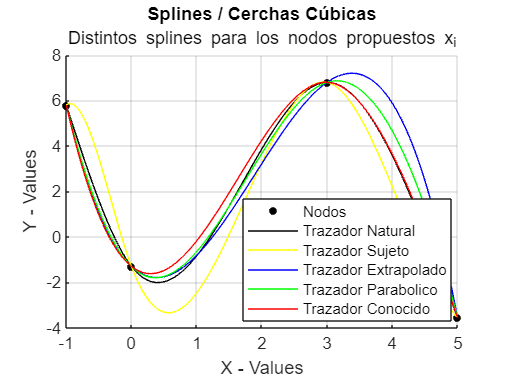


    if rem(i,2) == 1
        plot(X0,YN,'k', 'HandleVisibility','off')
        plot(X0,YF,'y', 'HandleVisibility','off')
        plot(X0,YE,'b', 'HandleVisibility','off')
        plot(X0,YCN,'g', 'HandleVisibility','off')
        plot(X0,YC,'r', 'HandleVisibility','off')
    else
        plot(X0,YN,'k')
        plot(X0,YF,'y')
        plot(X0,YE,'b')
        plot(X0,YCN,'g')
        plot(X0,YC,'r')
    end
end

grid on
legend('Nodos', 'Trazador Natural', 'Trazador Sujeto', 'Trazador Extrapolado', ...
                    'Trazador Parabolico', 'Trazador Conocido', 'Location', 'best')
title('Splines / Cerchas Cúbicas')
subtitle('Distintos splines para los nodos propuestos x_i')
ylabel('Y - Values')
xlabel('X - Values')
hold off